clear
clc
close all

syms Ki Kp Kd s
Psym = (2*s+1)/(s^3+8*s^2+15*s)

$$Psym = \frac{2\,s+1}{s^{3}+8\,s^{2}+15\,s}$$

Propongo:

Gc1 = Ki/s;
Gc2 = Kp + Kd * s;
GYD_sym = simplify(Psym /(1+Psym*(Gc1+Gc2)))

$$GYD\_sym = \frac{2\,s+1}{\left(\frac{\left(2\,s+1\right)\,\left(\mathrm{Kp}+\mathrm{Kd}\,s+\frac{\mathrm{Ki}}{s}\right)}{s^{3}+8\,s^{2}+15\,s}+1\right)\,\left(s^{3}+8\,s^{2}+15\,s\right)}$$

GYR_sym = simplify(GYD_sym*Gc1)

$$GYR\_sym = \frac{\mathrm{Ki}\,\left(2\,s+1\right)}{s\,\left(\frac{\left(2\,s+1\right)\,\left(\mathrm{Kp}+\mathrm{Kd}\,s+\frac{\mathrm{Ki}}{s}\right)}{s^{3}+8\,s^{2}+15\,s}+1\right)\,\left(s^{3}+8\,s^{2}+15\,s\right)}$$

Encontrar los coeficientes

z = 0.5;
ts = 1;
w = 4/(z*ts);

[num, den] = numden(GYD_sym);
num = expand(num);
coeffs_num = coeffs(num,s,'All');
den = expand(den);
coeffs_den = coeffs(den, s, 'All')

$$coeffs\_den = \left(\begin{array}{ccccc} 1 & 2\,\mathrm{Kd}+8 & \mathrm{Kd}+2\,\mathrm{Kp}+15 & 2\,\mathrm{Ki}+\mathrm{Kp} & \mathrm{Ki} \end{array}\right)$$

coeffs_den_norm = simplify(coeffs_den/(coeffs_den(1)))

$$coeffs\_den\_norm = \left(\begin{array}{ccccc} 1 & 2\,\mathrm{Kd}+8 & \mathrm{Kd}+2\,\mathrm{Kp}+15 & 2\,\mathrm{Ki}+\mathrm{Kp} & \mathrm{Ki} \end{array}\right)$$

poli_2do_orden1 = s^2 + 2*z*w*s + w^2;
poli_2do_orden2 = (s+10)*(s+8);
polinomio_deseado = poli_2do_orden1*poli_2do_orden2;
coeffs_deseado = coeffs(expand(polinomio_deseado), s, 'All')

$$coeffs\_deseado = \left(\begin{array}{ccccc} 1 & 26 & 288 & 1792 & 5120 \end{array}\right)$$

Resolución de sistema de ecuaciones

eqs = coeffs_den_norm(2:4) == coeffs_deseado(2:4)

$$eqs = \left(\begin{array}{ccc} 2\,\mathrm{Kd}+8=26 & \mathrm{Kd}+2\,\mathrm{Kp}+15=288 & 2\,\mathrm{Ki}+\mathrm{Kp}=1792 \end{array}\right)$$

S = solve(eqs, [Ki, Kp, Kd]);
Ki = double(S.Ki(1))

Ki = 830

Kp = double(S.Kp(1))

Kp = 132

Kd = double(S.Kd(1))

Kd = 9

Numéricamente

P = tf([2 1], [1 8 15 0])

P =
 
       2 s + 1
  ------------------
  s^3 + 8 s^2 + 15 s
 
Continuous-time transfer function.




Gc1 = tf([0 Ki],[1 0])

Gc1 =
 
  830
  ---
   s
 
Continuous-time transfer function.



Gc2 = tf([Kd Kp],1)

Gc2 =
 
  9 s + 132
 
Continuous-time transfer function.



GYD = feedback(P,(Gc1+Gc2))

GYD =
 
                2 s^2 + s
  -------------------------------------
  s^4 + 26 s^3 + 288 s^2 + 1792 s + 830
 
Continuous-time transfer function.



GYR = GYD * Gc1

GYR =
 
              1660 s^2 + 830 s
  -----------------------------------------
  s^5 + 26 s^4 + 288 s^3 + 1792 s^2 + 830 s
 
Continuous-time transfer function.



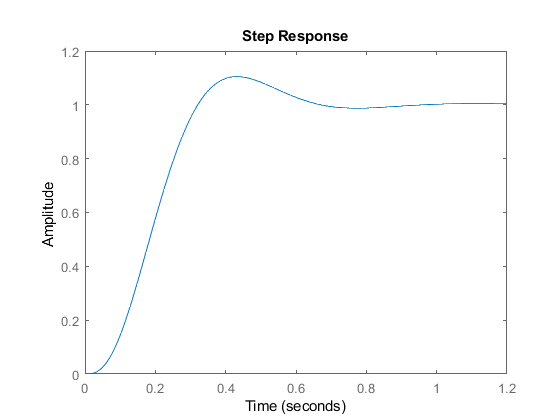

step(GYR)

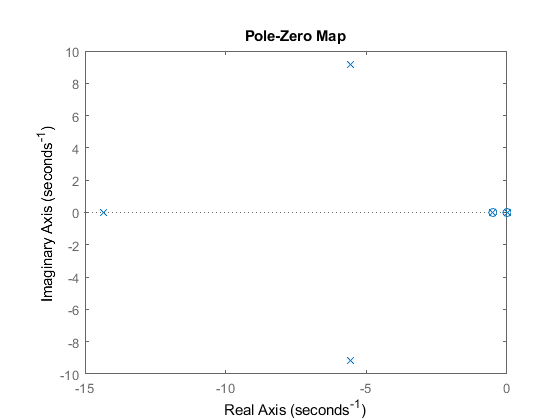

pzmap(GYR)

stepinfo(GYR)

ans = struct with fields:
        RiseTime: 0.1963
    SettlingTime: 0.6162
     SettlingMin: 0.9010
     SettlingMax: 1.1048
       Overshoot: 10.4800
      Undershoot: 0
            Peak: 1.1048
        PeakTime: 0.4300


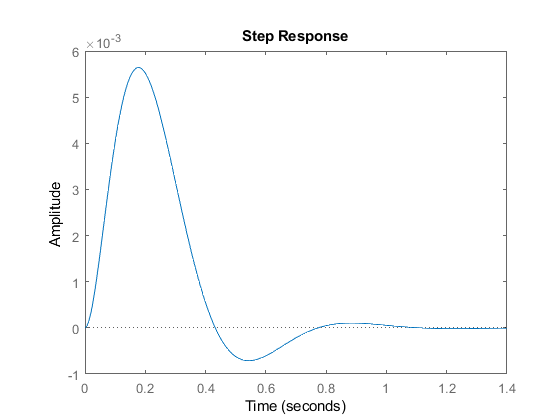

step(GYD)

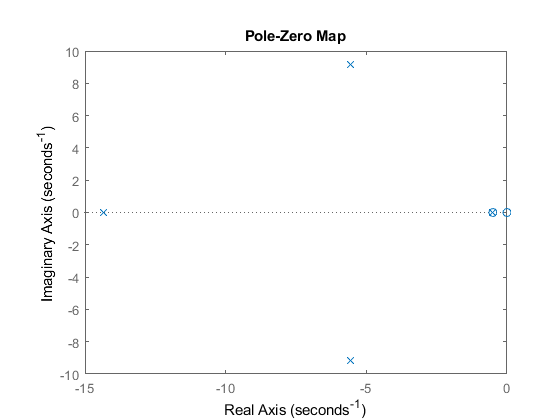

pzmap(GYD)

stepinfo(GYD)

ans = struct with fields:
        RiseTime: 0
    SettlingTime: 0.7303
     SettlingMin: -7.1168e-04
     SettlingMax: 0.0056
       Overshoot: Inf
      Undershoot: Inf
            Peak: 0.0056
        PeakTime: 0.1797
